# 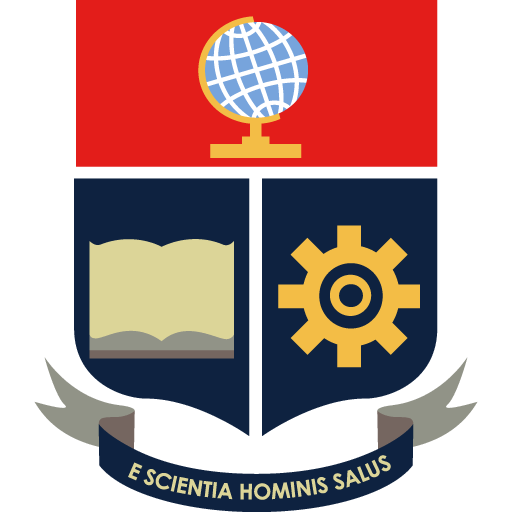

# **Movimiento**

- Asegúrese de estar utilizando el brazalete


Inicio de toma de datos
Right
In Pitch limits
Fuera


Simulación terminada en:


tiempo = 51.5900

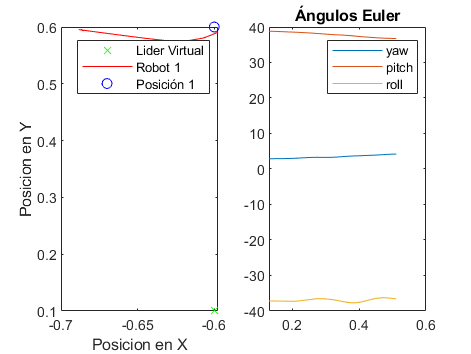


Inicio de toma de datos
Right
Down
Fuera


Simulación terminada en:


tiempo = 111.4000

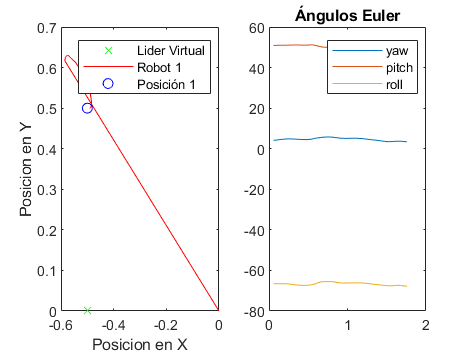

 
if server.NumBytesAvailable~=0
data=read(server,server.NumBytesAvailable,"uint8");
option=data(length(data));
end
pause(0.1);

% install_myo_mex; % adds directories to MATLAB search path
% % install_myo_mex save % additionally saves the path
% sdk_path = 'C:\myo-sdk-win-0.9.0'; % root path to Myo SDK
% build_myo_mex(sdk_path); % builds myo_mex

% while option~=6
% out0=sim('paraprueba.slx');
% end

vectorx=[];
vectory=[];
posicionx1=[];
posiciony1=[];
T_imu=[];
euAng=[];
i=1;
j=1;
k=1;
while option ~=4
%lectura del gesto
    if server.NumBytesAvailable~=0
    data=read(server,server.NumBytesAvailable,"uint8");
    option=data(length(data));
    switch option
        case 1
            gesim="1.png";gesto="Gesto - Wave out";
        case 2
            gesim="2.png";gesto="Gesto - Wave in";
        case 3
            gesim="3.png";gesto="Gesto - Fist";
        case 4
            gesim="4.png";gesto="Gesto - Open";
        case 5
            gesim="5.png";gesto="Gesto - Pinch";
        otherwise
            gesim="6.png";gesto="Relajado - No Gesture";
    end
    end
    %fin de lectura del gesto
%run formimg.m
run movimiento.m
run moving.m

tiempo=simtime(length(simtime));
printStatus(tiempo)

% movimiento.m :
% [yaw,pitch,roll,timeIMU,eulerAngles]=GetIMU();
% if yaw==1
%     x=x+0.1;
% elseif yaw==2
%     x=x-0.1;
% end
% 
% if pitch==1
%     y=y+0.1;
% elseif pitch==2
%     y=y-0.1;
% end
% 
% if escena==1
%     sim("OneRobot.slx");
% elseif escena==2
%     sim("Mtest5.slx");
% end
% disp("Simulación terminada en:")
% tiempo=simtime(length(simtime))


    vectorx(i)=x;
    vectory(i)=y;
    i=i+1;
    for jj=1:length(PosX1)
    posicionx1(j)=PosX1(jj);
    posiciony1(j)=PosY1(jj);
    j=j+1;
    end
    for kk=1:length(timeIMU)
    T_imu(k)=timeIMU(kk);
    euAng(k)=eulerAngles(kk);
    k=k+1;
    end


% figure;
%         subplot(1,2,1)
%         plot(x,y,'gx')
%         hold on
%         plot(PosX1,PosY1,'r')
%         plot(x+rx1,y+ry1,'bo')
%         xlabel('Posicion en X')
%         ylabel('Posicion en Y')
%         legend('Lider Virtual','Robot 1','Posición 1')
% 
%         subplot(1,2,2)
%         plot(timeIMU,eulerAngles); title('Ángulos Euler'); legend('yaw','pitch','roll');

pause(0.1);
%fin de contenido de while
end


vectrx1=vectorx+rx1*ones(length(vectorx));
vectry1=vectory+ry1*ones(length(vectory));

figure;
        subplot(1,2,1)
        plot(vectorx,vectory,'gx')
        hold on
        plot(posicionx1,posiciony1,'r')
        plot(vectrx1,vectry1,'bo')
        xlabel('Posicion en X')
        ylabel('Posicion en Y')
        legend('Lider Virtual','Robot 1','Posición 1')
        title('Movimiento realizado')

        subplot(1,2,2)
        plot(T_imu,euAng); title('Ángulos Euler realizados'); legend('yaw','pitch','roll');

disp("Saliendo de Movimiento")
pause(1)
open("menu.mlx")

function printStatus (mssg)
     if ind == 1
         % The very first time we don't need to delete the old text
         fprintf('Simulación terminada en: %.2f', mssg);
     else
        % Each \b removes one character from the previous fprintf.
        fprintf('\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\b\bSimulación terminada en: %.2f', mssg);
     end
end